## **Digital Communication Systems Laboratory**

## **Laboratory 05**

### **Section 01**

The initial parameters are usually defined at the beginning of the program.

clc; clear;
%tuid 915614617
A = 8;              % Signal amplitude
rb = 20;          % Fundamental frequency of signal
Tb = 1 / rb;        % Period of signal
fc = (20+6) * rb;
Tc = 1 / fc;
fs = 100 * fc;     % Sampling frequency
Ts = 1 / fs;        % Sampling period

### Section 02

#### **Baseband vs Passband**

Any passband modulation is an extension to its baseband modulation.

In the baseband:

    
$$s_{\textrm{base}} \left(t\right)=A\;\sin \left(\;2\pi \;f\;t+\phi \;\right)$$


    If the message is embedded in the amplitude A, the encoding is called Amplitude Shift Keying (ASK).

    If the message is embedded in the frequency *f*, the encoding is called Frequency Shift Keying (FSK).

    If the message is embedded in the phase $\phi$, the encoding is called Phase Shift Keying (PSK).

In the passband, the wave spectrum is transfered from the origin to a higher frequency, called as frequency of carrier or fc.

    
$$s_{\textrm{pass}} \left(t\right)=s_{\textrm{base}} \left(t\right)\cos \left(2\pi \;f_c \;t\right)=A\;\sin \left(2\pi \;r_b \;t+\phi \;\right)\;\cos \left(2\pi \;f_c \;t\right)$$


### Section 03

#### Amplitude Shift Keying (ASK) in the Passband

Suppose there are 4 symbols in the symbol set. Therefore, at least 4 bits are needed to encode the symbols in binary format.

M = 16;                  % Number of symbols
Nb = ceil(log2(M));     % Number of bits per symbol

In ASK encoding, the amplitude will carry the information. So, the amplitude of the sinosoid will be changed by the symbols.

For example:


$$\begin{array}{l}
\textrm{Symbol}\;0:\;\textrm{Amplitude}=-A\\
\textrm{Symbol}\;1:\textrm{Amplitude}=-\frac{A}{2}\\
\textrm{Symbol}\;2:\textrm{Amplitude}=+\frac{A}{2}\\
\textrm{Symbol}\;3:\textrm{Amplitude}=+A
\end{array}$$


This symbol sets can be shown in the original indices and the ASK encoded format:

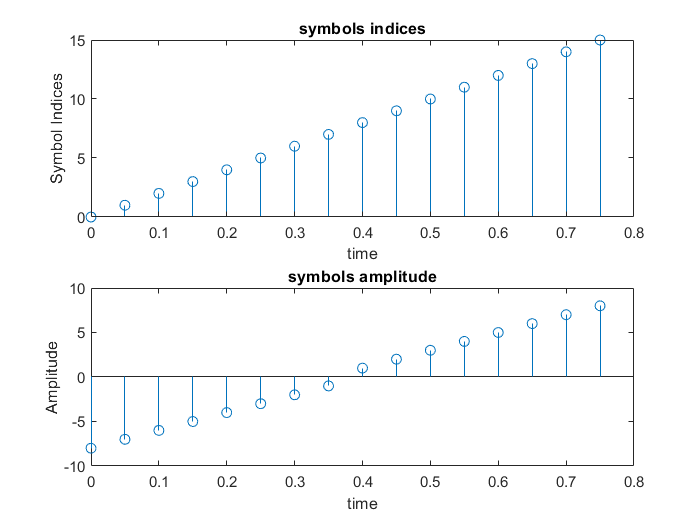

symbol_set = 0:(M-1);                          % symbols' indices
symbol_amplitude = [-(M/2):-1, 1:(M/2)] * 2 * A / M;            % symbols' amplitude
msg = 0:(M-1);                     % message: a set of symbols
%msg=[9,1,5,6,1,4,6,1,7]
msg_amplitude = symbol_amplitude(symbol_set(msg+1)+1);  % mepping the symbol to the amplitude
t = (0:length(msg)-1)*Tb;
figure()
subplot(2, 1, 1); stem(t, msg); xlabel('time'); ylabel('Symbol Indices'); title('symbols indices');
subplot(2, 1, 2); stem(t, msg_amplitude); xlabel('time'); ylabel('Amplitude'); title('symbols amplitude');

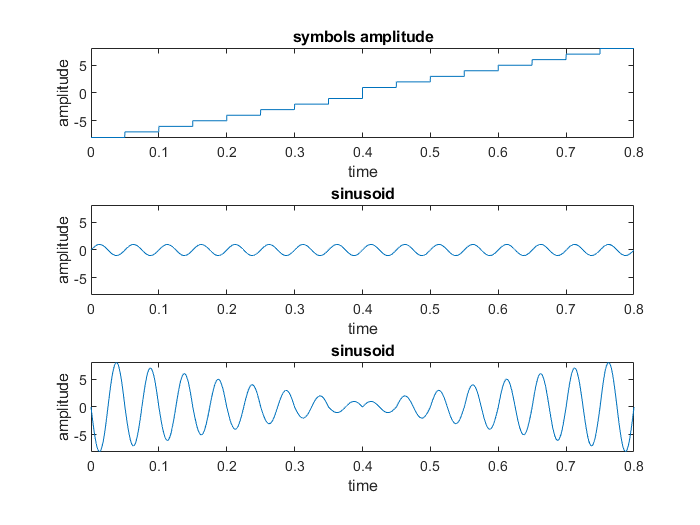

amplitudes = rate_transition(msg_amplitude, rb, fs);
t = (0:length(amplitudes)-1)*Ts;
sin_signal = 1 * sin(2 * pi * rb * t + 0);
signal = amplitudes .* sin_signal;
figure()
subplot(3, 1, 1); plot(t, amplitudes); xlabel('time'); ylabel('amplitude'); ylim([-A-0.1, +A+0.1]); title('symbols amplitude')
subplot(3, 1, 2); plot(t, sin_signal); xlabel('time'); ylabel('amplitude'); ylim([-A-0.1, +A+0.1]); title('sinusoid');
subplot(3, 1, 3); plot(t, signal); xlabel('time'); ylabel('amplitude'); ylim([-A-0.1, +A+0.1]); title('sinusoid');

The baseband signal is modulated with carrier signal and the spectrum will shift in frequency domain from around the origin to the  Hertz.

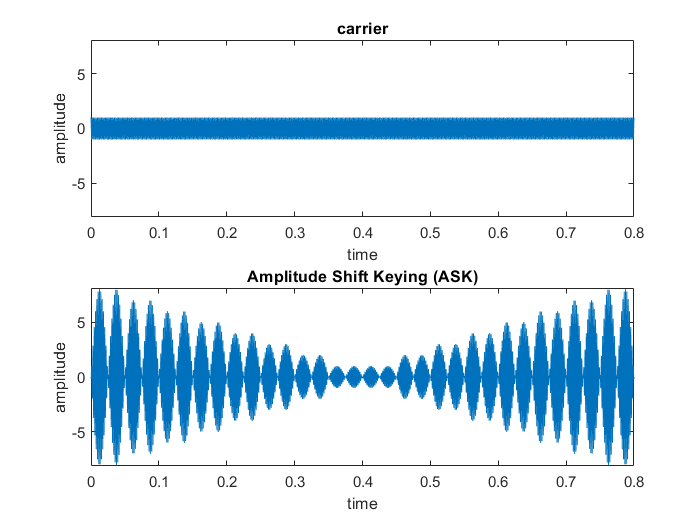

carrier = 1 * cos(2 * pi * fc * t + 0);
modulated = signal .* carrier;
figure()
subplot(2, 1, 1); plot(t, carrier); xlabel('time'); ylabel('amplitude'); ylim([-A-0.1, +A+0.1]); title('carrier');
subplot(2, 1, 2); plot(t, modulated); xlabel('time'); ylabel('amplitude'); ylim([-A-0.1, +A+0.1]); title('Amplitude Shift Keying (ASK)');

### Section 04

#### Demodulation, Decoding, and Detection

Demodulation is the inverse of modulation, but the operation is the same.


$$r_{\textrm{pass}} \left(t\right)=s_{\textrm{base}} \left(t\right)\cos \left(2\pi \;f_c \;t\right)=A\;\sin \left(2\pi \;r_b \;t+\phi \;\right)\;\cos \left(2\pi \;f_c \;t\right)$$



$$r_{\textrm{base}} \left(t\right)=\int_0^{T_c } r_{\textrm{pass}} \left(t\right)\cos \left(2\pi \;f_c \;t\right)\textrm{dt}=\int_0^{T_c } s_{\textrm{base}} \left(t\right)\cos \left(2\pi \;f_c \;t\right)\cos \left(2\pi \;f_c \;t\right)\textrm{dt}$$


Since it is assumed that $r_b \ll f_c$, it can be found that the variation of $s_{\textrm{base}} \left(t\right)=A\;\sin \left(2\pi \;r_b \;t+\phi \;\right)$ is much less than $\cos \left(2\pi \;f_c \;t\right)$ in one period of carrier frequency ($T_c$). Therefore, it can be assumed that $s_{\textrm{base}} \left(t\right)$is almost constant in one cycle of carrier and the integral can be rewriten as:


$$r_{\textrm{base}} \left(t\right)\approx s_{\textrm{base}} \left(t\right)\int_0^{T_c } \cos^2 \left(2\pi \;f_c \;t\right)\textrm{dt}=\frac{s_{\textrm{base}} \left(t\right)}{2}\int_0^{T_c } 1+\cos \left(4\pi \;f_c \;t\right)\;\textrm{dt}=\frac{T_c }{2}s_{\textrm{base}} \left(t\right)$$


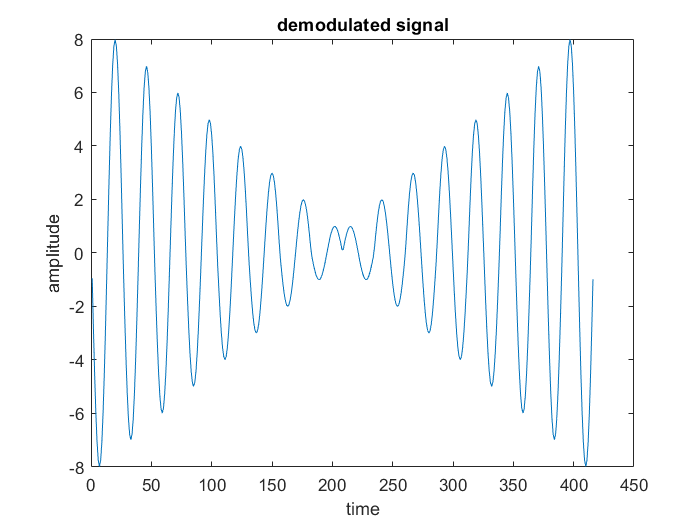

% demodulation
rt = modulated;
Ns = round(fs / fc);
demodulated = zeros([1, floor(length(rt) * fc/fs)]);
dcounter = 1;
for n = Ns:Ns:length(rt)
    r_hat_t = rt(n-Ns+1:n) .* cos(2*pi*fc*(0:Ns-1)*Ts);
    demodulated(dcounter) = sum(r_hat_t)*Ts*2/Tc;
    dcounter = dcounter + 1;
end
% demodulated = rate_transition(demodulated, fc, fs);
figure()
plot(demodulated); xlabel('time'); ylabel('amplitude'); title('demodulated signal');

Decoding tries to find the indices of transmitted symbols.

Detection means to find the message that has been transmitted.

There are several methods to decode the received signal, but the correlation decoder is the most common. The matched filter is an LTI implementation of correlator, so both are the same with different formulation.

If the received signal is $r\left(t\right)$ and the base encoding signal is $s\left(t\right)$ then correlator decoder works as follow:


$$a=\int_0^{T_s } r\left(t\right)s\left(t\right)\textrm{dt}$$


The detection will be done with coefficient $a$, for example with a threshold.

If we have several base encoding signal ($s_i \left(t\right)$) then several coefficients will be computed as follow:


$$a_i =\int_0^{T_s } r\left(t\right)s_i \left(t\right)\textrm{dt}$$


Then detection will be done with all coefficiens $\left\lbrace a_1 ,a_2 ,\;\ldotp \ldotp \ldotp ,a_m \right\rbrace$

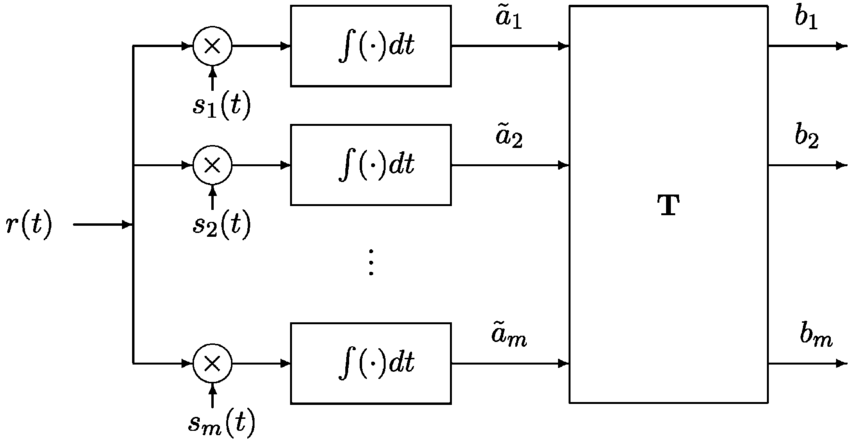

### Section 05

#### ASK Correlator Decoder and Detection

Since only a single sinusoid has used for encoding, a single correlator will be enough for detection.


$$a=\int_0^{T_b } r\left(t\right)\sin \left(2\pi \textrm{ft}\right)\textrm{dt}$$


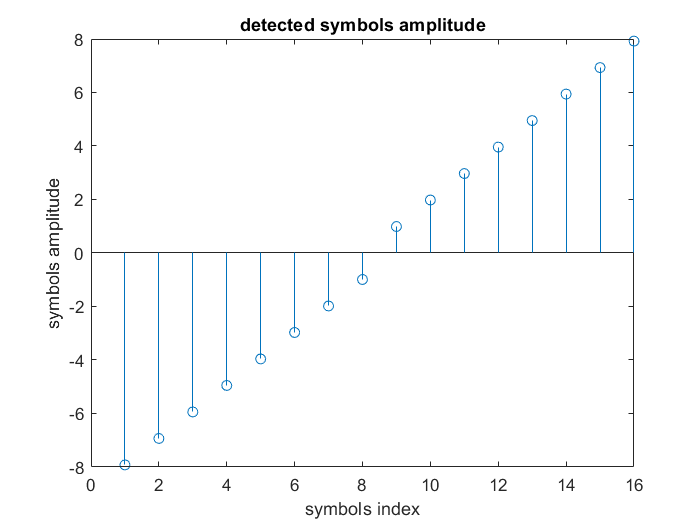

% decoding
rt = demodulated;
Ns = round(fc / rb);
dec_signal = zeros([1, floor(length(rt) * rb / fc)]);
dcounter = 1;
for n = Ns:Ns:length(rt)
    r_hat_t = rt(n-Ns+1:n) .* sin(2*pi* (fc/rb) * (0:Ns-1)/Ns * Tc/Tb);
    dec_signal(dcounter) = sum(r_hat_t)*(Tc/Tb)*2;
    dcounter = dcounter + 1;
end
figure()
stem(dec_signal); xlabel('symbols index'); ylabel('symbols amplitude'); title('detected symbols amplitude');

% detection
% finding the unique levels
levels = [-inf, unique(round(dec_signal, 2)), inf]

levels =       -Inf   -7.9200   -6.9300   -5.9400   -4.9500   -3.9600   -2.9700   -1.9800   -0.9900    0.9900    1.9800    2.9700    3.9600    4.9500    5.9400    6.9300    7.9200       Inf


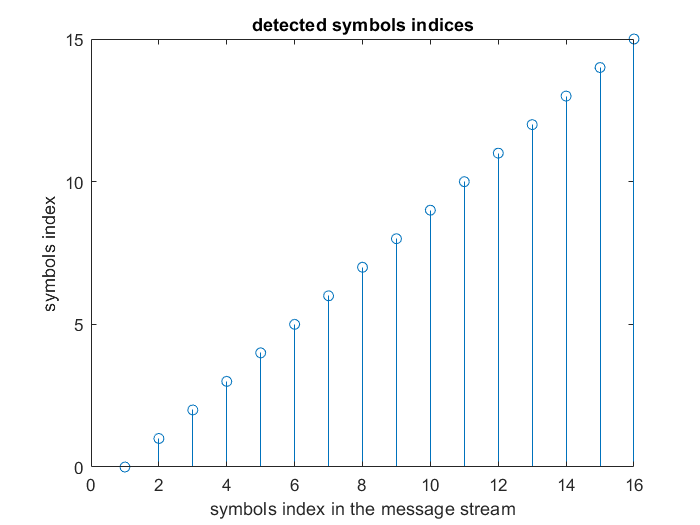

% levels = [-inf, -7.92, -6.39, -5.94, -4.95, -3.96, -2.97, -1.98, -0.99, 0.99, 1.98, 2.97, 3.96, 4.95, 5.94, 6.93, 7.92, inf];
% finding the thresholds
thresholds = (levels(2:end) + levels(1:end-1))/2;
detected_indices = zeros([1, length(dec_signal)]);
for n = 1:length(dec_signal)
    if length(thresholds(thresholds == dec_signal(n))) == 0
        lvl = sort([thresholds, dec_signal(n)]);
    end
    indices = 1:length(lvl);
    detected_indices(n) = indices(lvl == dec_signal(n))-2;
end
figure()
stem(detected_indices); xlabel('symbols index in the message stream'); ylabel('symbols index'); title('detected symbols indices');

% computing error rates
err = mean(msg ~= detected_indices)

err = 0

### Section 06

#### Noise

Noise is the impact of channel that signal transfer through.

The most common way to find the noise impact is Additive White Gaussian Noise (AWGN) model. In this model, the noise will be generted by a Gaussian distribution and added to the transmitted signal.

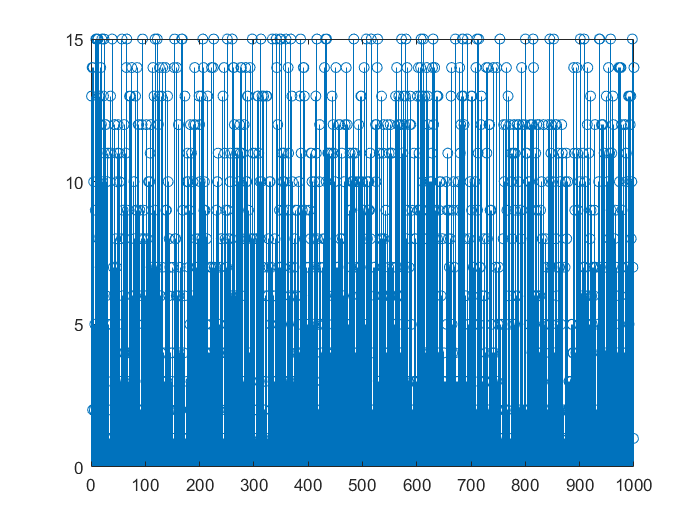

% generation of a random message with fixed length
rng(0);
Nm = 1000;
msg = randi(M-1, [1, Nm]);                            % message: a set of symbols
figure(); stem(msg);

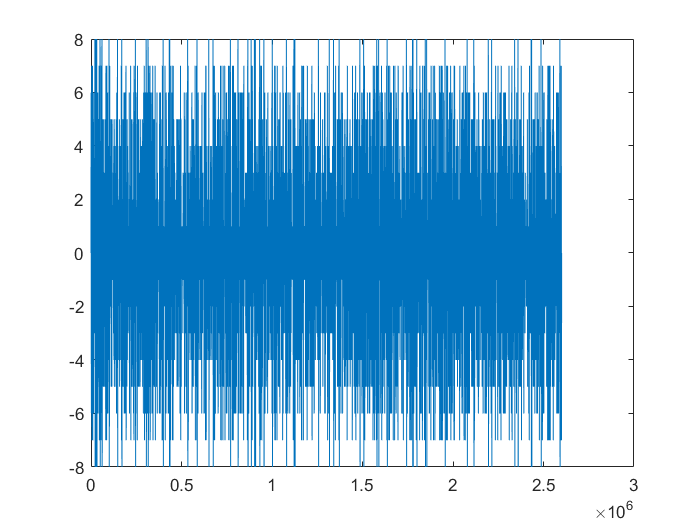

msg_amplitude = symbol_amplitude(symbol_set(msg+1)+1);  % mepping the symbol to the amplitude
amplitudes = rate_transition(msg_amplitude, rb, fs); % translate rate 1 to rate rb
t = (0:length(amplitudes)-1)*Ts;                    % make the parameter time
sin_signal = 1 * sin(2 * pi * rb * t + 0);          % simple sinusoid wave
signal = amplitudes .* sin_signal;                  % message multiply by sinusoid
figure(); plot(signal);

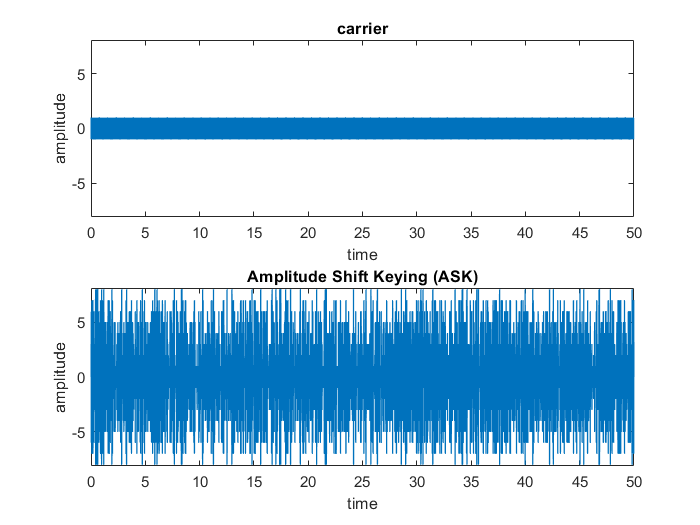

carrier = 1 * cos(2 * pi * fc * t + 0);
modulated = signal .* carrier;
figure()
subplot(2, 1, 1); plot(t, carrier); xlabel('time'); ylabel('amplitude'); ylim([-A-0.1, +A+0.1]); title('carrier');
subplot(2, 1, 2); plot(t, modulated); xlabel('time'); ylabel('amplitude'); ylim([-A-0.1, +A+0.1]); title('Amplitude Shift Keying (ASK)');

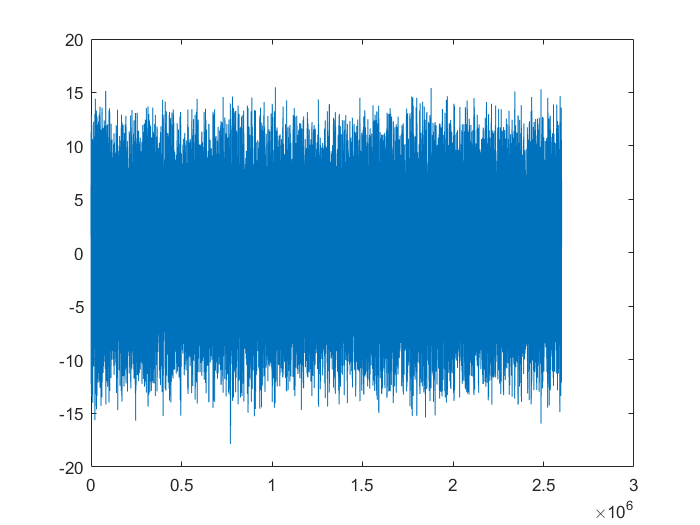

snr = 0;
noisy_signal = awgn(modulated, snr, 'measured');
figure(); plot(noisy_signal);

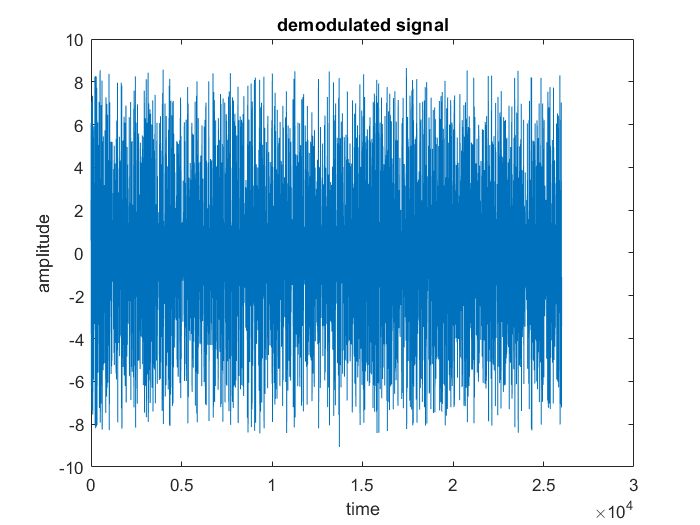

% demodulation
rt = noisy_signal;
Ns = round(fs / fc);
demodulated = zeros([1, floor(length(rt) * fc/fs)]);
dcounter = 1;
for n = Ns:Ns:length(rt)
    r_hat_t = rt(n-Ns+1:n) .* cos(2*pi*fc*(0:Ns-1)*Ts);
    demodulated(dcounter) = sum(r_hat_t)*Ts*2/Tc;
    dcounter = dcounter + 1;
end
figure()
plot(demodulated); xlabel('time'); ylabel('amplitude'); title('demodulated signal');

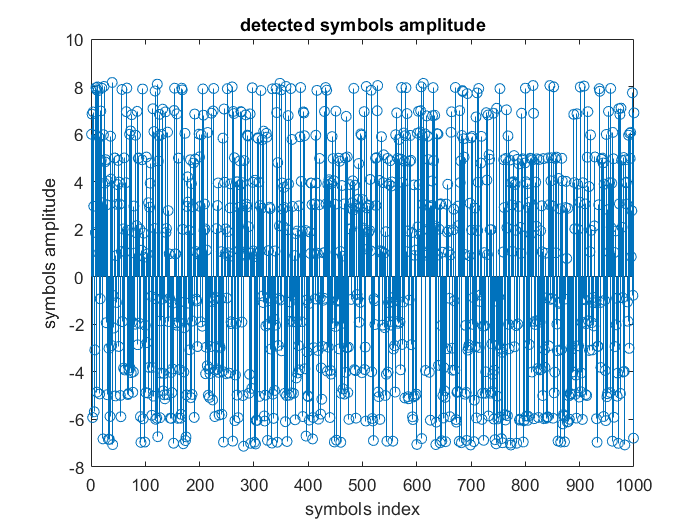

% decoding
rt = demodulated;
Ns = round(fc / rb);
dec_signal = zeros([1, floor(length(rt) * rb / fc)]);
dcounter = 1;
for n = Ns:Ns:length(rt)
    r_hat_t = rt(n-Ns+1:n) .* sin(2*pi* (fc/rb) * (0:Ns-1)/Ns * Tc/Tb);
    dec_signal(dcounter) = sum(r_hat_t)*(Tc/Tb)*2;
    dcounter = dcounter + 1;
end
figure()
stem(dec_signal); xlabel('symbols index'); ylabel('symbols amplitude'); title('detected symbols amplitude');

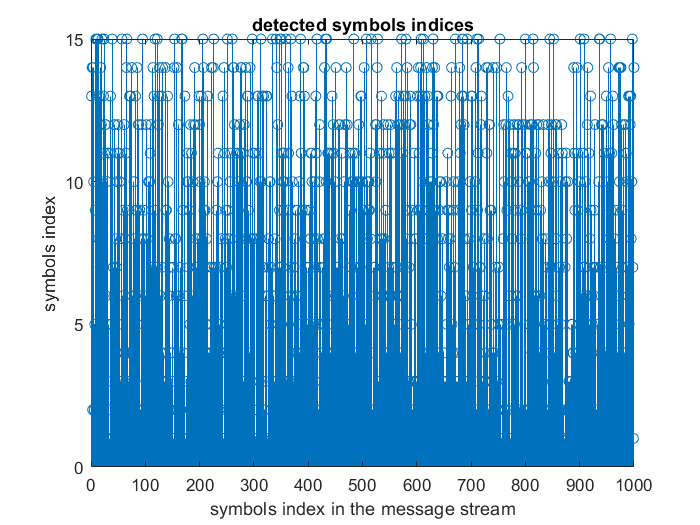

% detection
detected_indices = zeros([1, length(dec_signal)]);
for n = 1:length(dec_signal)
    if length(thresholds(thresholds == dec_signal(n))) == 0
        lvl = sort([thresholds, dec_signal(n)]);
    end
    indices = 1:length(lvl);
    detected_indices(n) = indices(lvl == dec_signal(n))-2;
end
figure()
stem(detected_indices); xlabel('symbols index in the message stream'); ylabel('symbols index'); title('detected symbols indices');

% computing error rates
err = mean(msg ~= detected_indices)

err = 0

### Section 07

Power spectrum of the **baseband** signal:

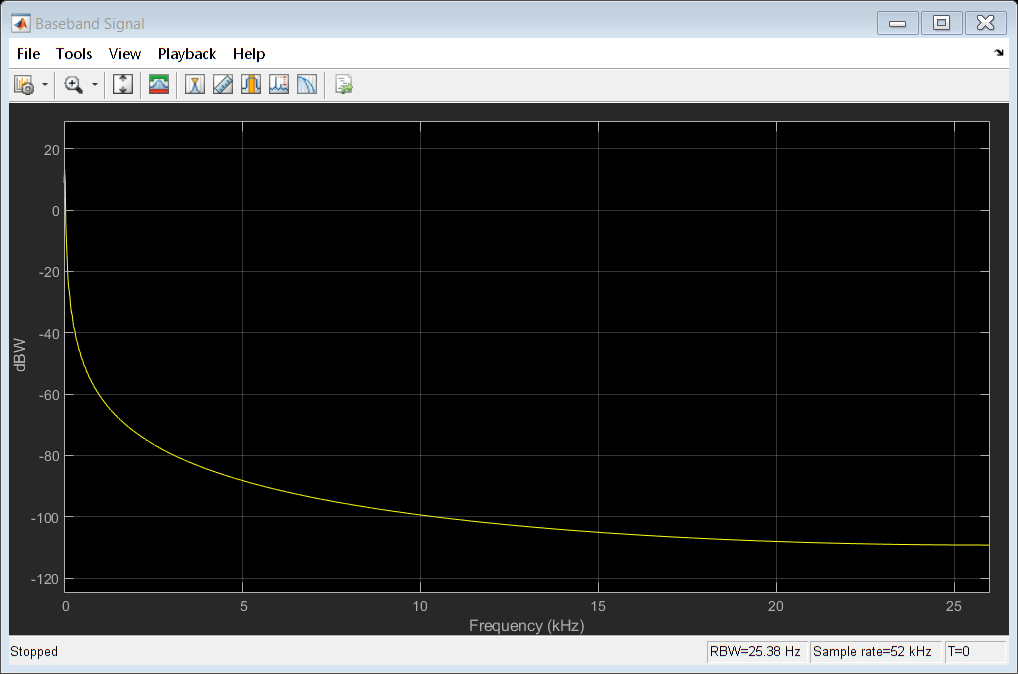

scope1 = dsp.SpectrumAnalyzer();
scope1.SampleRate = fs;
scope1.PlotAsTwoSidedSpectrum = false;
scope1.SpectrumUnits = "dBW";
scope1(signal');
scope1.Name = 'Baseband Signal';
release(scope1);

Power spectrum of the **carrier** signal:

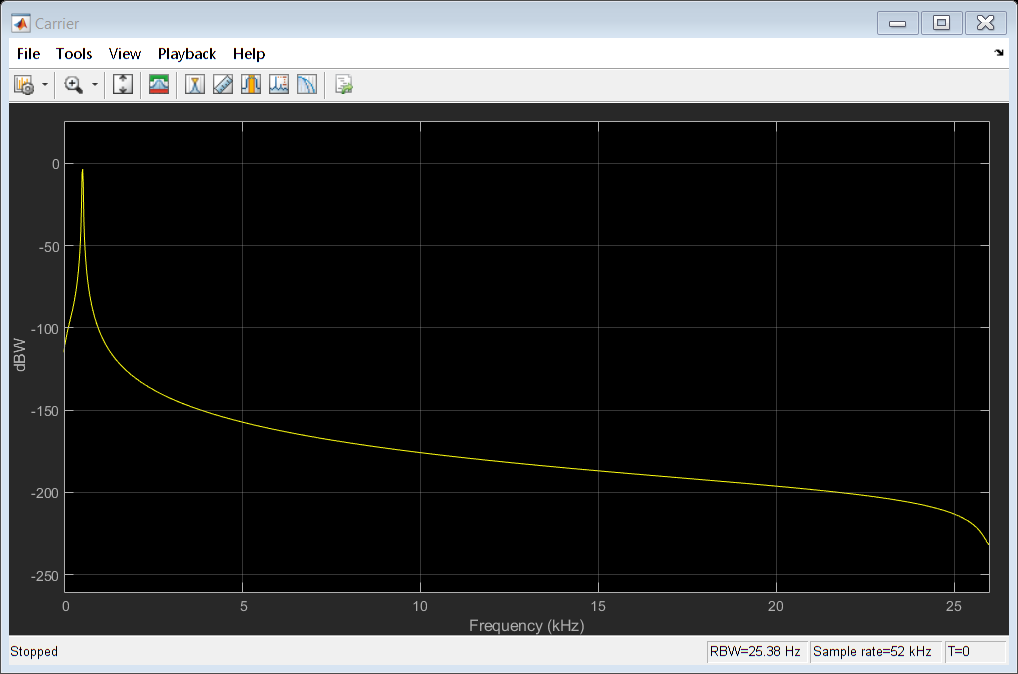

scope2 = dsp.SpectrumAnalyzer();
scope2.SampleRate = fs;
scope2.PlotAsTwoSidedSpectrum = false;
scope2.SpectrumUnits = "dBW";
scope2(carrier');
scope2.Name = 'Carrier';
release(scope2);

Power spectrum of the **modulated (passband)** signal:

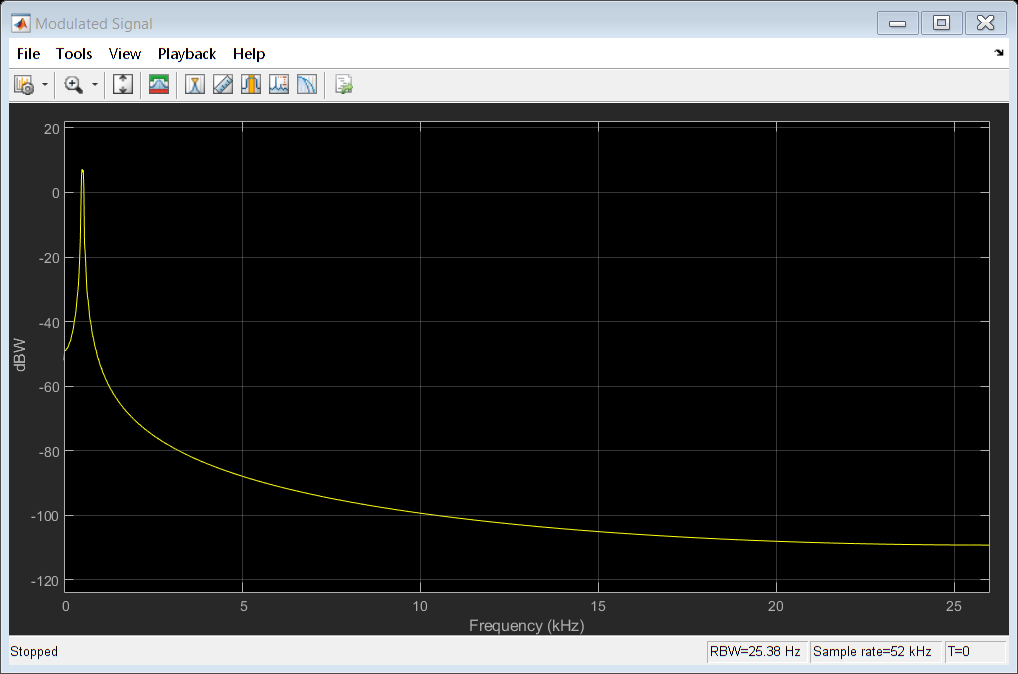

scope3 = dsp.SpectrumAnalyzer();
scope3.SampleRate = fs;
scope3.PlotAsTwoSidedSpectrum = false;
scope3.SpectrumUnits = "dBW";
scope3(modulated');
scope3.Name = 'Modulated Signal';
release(scope3);

Power spectrum of the **recieved** signal:

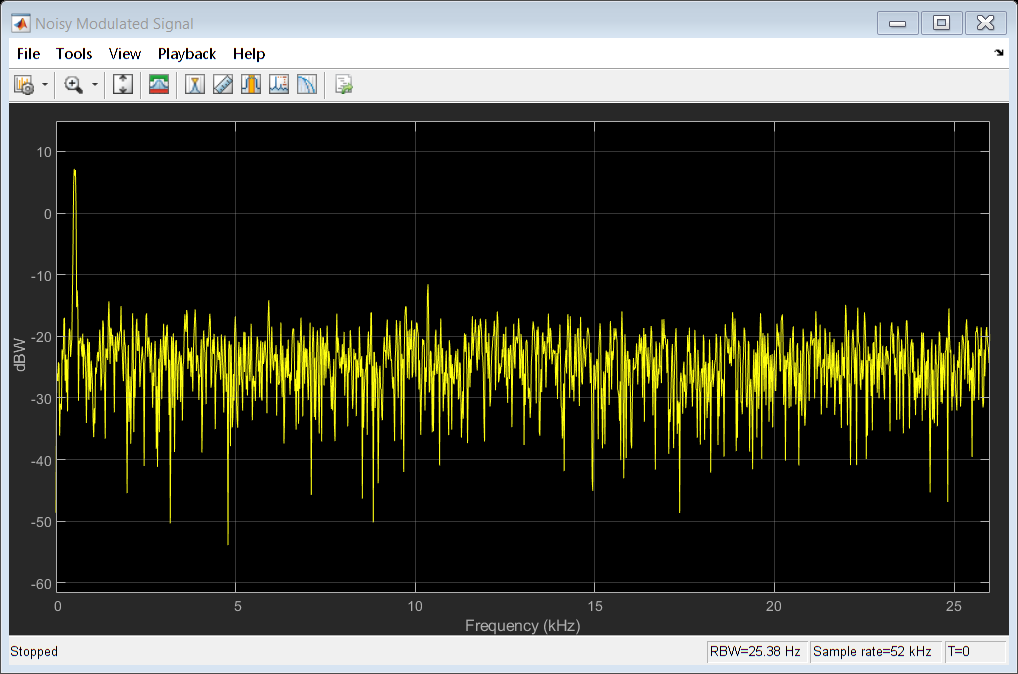

scope4 = dsp.SpectrumAnalyzer();
scope4.SampleRate = fs;
scope4.PlotAsTwoSidedSpectrum = false;
scope4.SpectrumUnits = "dBW";
scope4(noisy_signal');
scope4.Name = 'Noisy Modulated Signal';
release(scope4);

### Functions Definition

Rate transition:

function rt = rate_transition(s, f1, f2)
    if (f1 < f2)
        rt = repelem(s, floor(f2/f1));
        % x = 0:1/f1:((length(s)-1)*1/f1);
        % xq = 0:1/f2:((length(s)-1)*1/f1);
        % rt = interp1(x, s, xq, 'linear');
    else
        step = floor(f1/f2);
        rt = s(1:step:end);
    end
end